# create demodulator under AWGN 

% Y = X + N
source_bit_length = 10000;
snr_range = 0:1:14;
max_iter = 100;
bit_error_count_threshold = 100;

ber_array = zeros(length(snr_range), 1);

for snr_index = 1:length(snr_range)
    snr_val = snr_range(snr_index);
    total_bit_error_num = 0; % Reset total_bit_error_num for each SNR value
    
    for iter = 1:max_iter
        % create source bits
        tx_bits = randi([0, 1], source_bit_length, 1);
        
        % create QAM symbols
        tx_symbols = qammod(tx_bits, 4, 'InputType', 'bit', 'UnitAveragePower', true); 
        
        % AWGN channel
        rx_symbols = awgn(tx_symbols, snr_val);
        
        % Demodulation into bits
        rx_bits = min_distance_qpsk_demodulation(rx_symbols);
    
        % count the number of unmatched bits
        bit_error_num = sum(tx_bits ~= rx_bits);
        total_bit_error_num = total_bit_error_num + bit_error_num;
        
        % Breaking conditions if total error number > threshold
        if total_bit_error_num > bit_error_count_threshold
            break;
        end
    
    end
    iter
    % Calculate BER
    ber = total_bit_error_num / (iter * source_bit_length);
    ber_array(snr_index) = ber;
end  

iter = 1

iter = 1

iter = 1

iter = 1

iter = 1

iter = 1

iter = 1

iter = 1

iter = 2

iter = 4

iter = 15

iter = 61

iter = 100

iter = 100

iter = 100

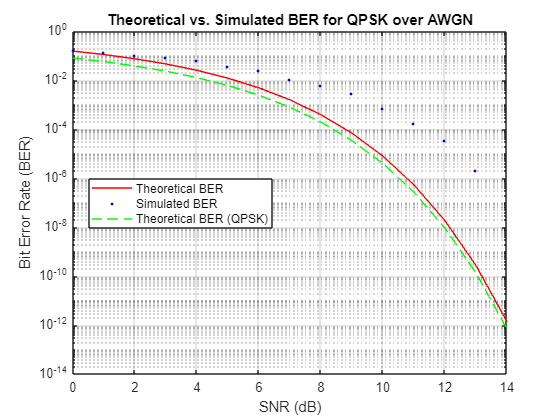

% Define parameters
snr_range_db = 0:1:14;  % SNR range in dB
snr_range_lin = 10.^(snr_range_db/10);  % Convert SNR range to linear scale (Power ratio)
theoretical_ber = 2 * qfunc(sqrt(2 * snr_range_lin)) - (qfunc(sqrt(2 * snr_range_lin))).^2; % q func Theoretical BER for QPSK over AWGN

% Plot
semilogy(snr_range_db, theoretical_ber, 'r-');  % Plot theoretical BER curve in red
hold on;
semilogy(snr_range_db, ber_array, 'b.');  % Plot simulated BER curve in blue circles
xlabel('SNR (dB)');
ylabel('Bit Error Rate (BER)');
title('Theoretical vs. Simulated BER for QPSK over AWGN');
legend('Theoretical BER', 'Simulated BER');
grid on;

% Plot theoretical BER for QPSK
EbNo = (0:14)';
M = 4; % Modulation order
berQ = berawgn(EbNo,'psk',M,'nondiff');
semilogy(EbNo, berQ, 'g--', 'DisplayName', 'Theoretical BER (QPSK)');
legend('Location', 'best');

hold off;

function recovered_bits = min_distance_qpsk_demodulation(rx_symbols)
    reference_symbols = [1+1i; -1+1i; -1-1i; 1-1i]/ sqrt(2);
    reference_symbols_corr_bits = [1 0;0 0;0 1 ; 1 1];
    
    % Initialize recovered bits
    source_bit_length = length(rx_symbols) * 2;
    recovered_bits = zeros(source_bit_length, 1);

    % Loop through received symbols
    for i = 1:length(rx_symbols)
        % Calculate Euclidean distances between received symbol and reference symbols
        distances = abs(rx_symbols(i) - reference_symbols);

        % Find index of the closest reference symbol
        [~, index] = min(distances);

        % Get the corresponding bits for the closest reference symbol
        bits = reference_symbols_corr_bits(index, :);

        % Assign the recovered bits
        recovered_bits((2*i-1):(2*i)) = bits;
    end
end